# SNW_DS_PARAM Tiny Solution Analysis

This is the example vignette for function: [**snw_ds_main**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/params/snw_ds_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for vfi and gets distribution induced by policy functions and exogenous distributions.

## Test SNW_DS_MAIN Defaults

Call the function with testing defaults. Note:

- mean of a_ss = mp_dsvfi_results('A_agg')/sum(Phi_true,'all')

- mean of c_ss = (mp_dsvfi_results('Y_inc_agg') - mp_dsvfi_results('Tax_revenues'))/sum(Phi_true,'all')

mp_params = snw_mp_param('default_tiny');
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = true;
mp_controls('bl_print_ds') = true;
mp_controls('bl_print_vfi_verbose') = false;
mp_controls('bl_print_ds_verbose') = false;
mp_controls('bl_vfi_store_all') = true;
mp_controls('bl_ds_store_all') = true;
[mp_dsvfi_results] = snw_ds_main(mp_params, mp_controls);

SNW_VFI_MAIN: Finished Age Group:7 of 7
SNW_VFI_MAIN: Finished Age Group:6 of 7
SNW_VFI_MAIN: Finished Age Group:5 of 7
SNW_VFI_MAIN: Finished Age Group:4 of 7
SNW_VFI_MAIN: Finished Age Group:3 of 7
SNW_VFI_MAIN: Finished Age Group:2 of 7
SNW_VFI_MAIN: Finished Age Group:1 of 7
Elapsed time is 92.574152 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=;default_tiny;SNW_MP_CONTROL=;default_test
SNW_DS_MAIN: Share of population with assets equal to upper bound on asset grid=0
SNW_DS_MAIN: Old and updated value of a2=1.9007      3.0621
Elapsed time is 100.646241 seconds.
Completed SNW_DS_MAIN;SNW_MP_PARAM=;default_tiny;SNW_MP_CONTROL=;default_test
xxx tb_outcomes: all stats xxx
    OriginalVariableNames       a_ss          ap_ss         c_ss          v_ss          n_ss    
    _____________________    __________    ___________    ___

## Show All Info in mp_dsvfi_results

ff_container_map_display(mp_dsvfi_results);

pos = 14 ; key = mp_cl_mt_xyz_of_s
  Map with properties:

        Count: 8
      KeyType: char
    ValueType: any

pos = 15 ; key = mp_controls
  Map with properties:

        Count: 18
      KeyType: char
    ValueType: any

pos = 16 ; key = mp_params
  Map with properties:

        Count: 29
      KeyType: char
    ValueType: any

----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_dsvfi_results ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                    i    idx    ndim    numel    rowN    colN       sum           mean          std       coefvari<

## Tiny Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Probability mass matrixes, Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 28:16:92, 100];
agrid = mp_params('agrid')';
eta_grid = mp_params('eta_grid')';
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'shock', eta_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Probability Mass Along Age Dimensions

Where are the mass at? Analyze mass given state space components.

% Get the Joint distribution over all states
Phi_true = mp_dsvfi_results('Phi_true');
Phi_true = Phi_true/sum(Phi_true(:));
% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Exogenous Permanent States Mass: Life Cycle, Edu and Marraige

Tabulate value and policies along savings and shocks:

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,5,4];
% Value Function
tb_prob_aem = ff_summ_nd_array("P(Age, EDU, MARRY))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, EDU, MARRY))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    marry    edu    sum_age_19    sum_age_28    sum_age_44    sum_age_60    sum_age_76    sum_age_92    sum_age_100
    _____    _____    ___    __________    __________    __________    __________    __________    __________    ___________

      1        0       0       0.10341      0.088137      0.074176      0.060895      0.045166      0.020405     0.00056524 
      2        1       0      0.080107      0.068273      0.057459      0.047171      0.034987      0.015806     0.00043785 
      3        0       1      0.034816      0.029673      0.024973      0.020501      0.015206     0.0068

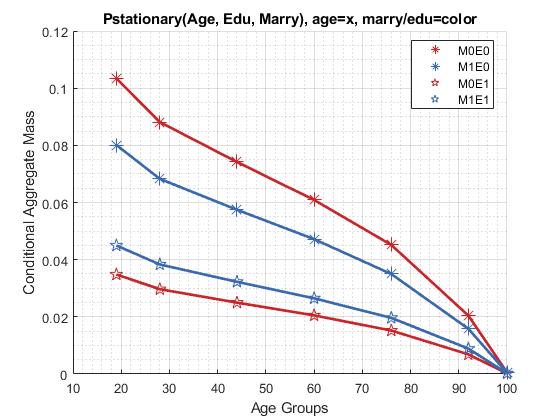

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Edu, Marry), age=x, marry/edu=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = ["M0E0", "M1E0", "M0E1", "M1E1"];
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
mp_support_graph('cl_scatter_shapes') = {'*', '*', 'p', 'p' };
mp_support_graph('cl_colors') = {'red', 'blue', 'red', 'blue'};
ff_graph_grid((tb_prob_aem{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

#### Kids and Marry By Age Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_prob_amarrykids = ff_summ_nd_array("P(Age, Kids, Marry))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, Kids, Marry))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    sum_age_19    sum_age_28    sum_age_44    sum_age_60    sum_age_76    sum_age_92    sum_age_100
    _____    ____    _____    __________    __________    __________    __________    __________    __________    ___________

      1       1        0        0.11238       0.08518      0.070338       0.05989       0.04799       0.023735    0.00070637 
      2       2        0       0.016997      0.021126       0.01796      0.013842     0.0086931       0.002746    4.1266e-05 
      3       3        0      0.0088548      0.011504      0.010851     0.0076654     0.0036888     

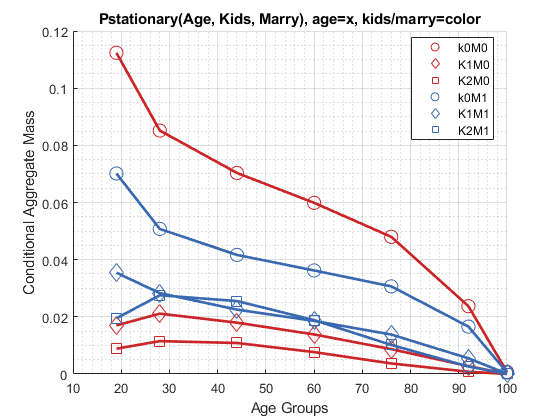

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Kids, Marry), age=x, kids/marry=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
ff_graph_grid((tb_prob_amarrykids{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Probability Mass Asset and Shock Dimensions

Where are the mass at?

% Get the Joint distribution over all states
Phi_true = mp_dsvfi_results('Phi_true');
Phi_true = Phi_true/sum(Phi_true(:));
% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Asset and Shock Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_prob_az = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings    sum_shock__0_72413    sum_shock__0_36206    sum_shock_0    sum_shock_0_36206    sum_shock_0_72413
    _____    _______    __________________    __________________    ___________    _________________    _________________

      1            0          0.054806                0.2043           0.28617           0.17557             0.037453    
      2      0.26063         0.0076517              0.045163          0.086232          0.069019             0.021346    
      3        2.085        4.2749e-05            0.00053733         0.0025961         0.0054096            0.0037006    
      4        7.037                 0                     0                 0                 0             

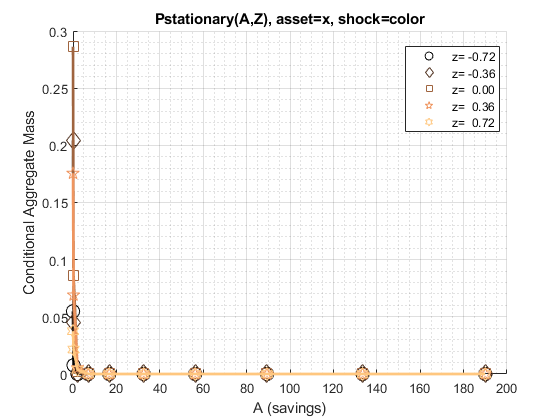

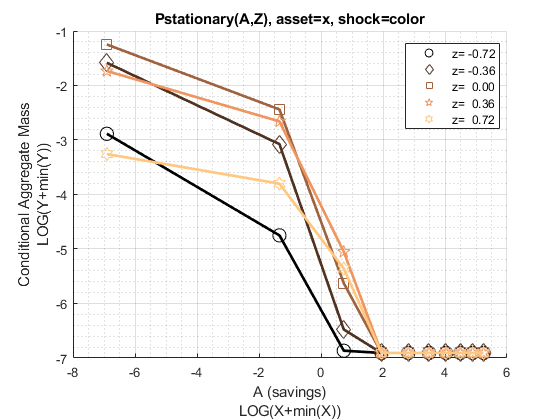

mp_support_graph('cl_st_graph_title') = {'Pstationary(A,Z), asset=x, shock=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'z=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.2f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_az{1:end, 3:end})', eta_grid, agrid, mp_support_graph);% Consumption Choices

#### Asset Mass by Age

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [3,4,5,6,1,2];
% Value Function
tb_prob_aage = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings    sum_age_19    sum_age_28    sum_age_44    sum_age_60    sum_age_76    sum_age_92    sum_age_100
    _____    _______    __________    __________    __________    __________    __________    __________    ___________

      1            0      0.2633        0.22235        0.17728     0.064338     0.0055496      0.024109      0.0013687 
      2      0.26063           0      0.0020524       0.011577     0.088757       0.10165      0.025301     7.0427e-05 
      3        2.085           0              0     1.1922e-06      0.00195     0.0077929     0.0025424              0 
      4        7.037           0              0    

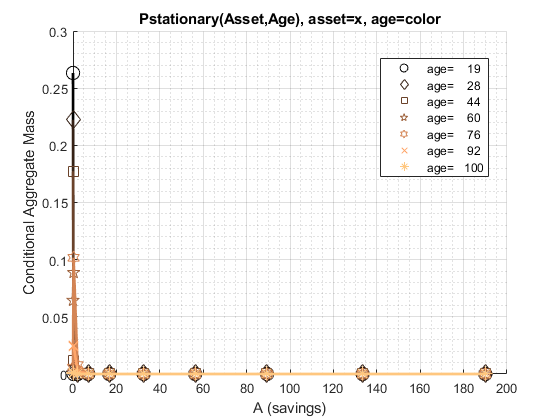

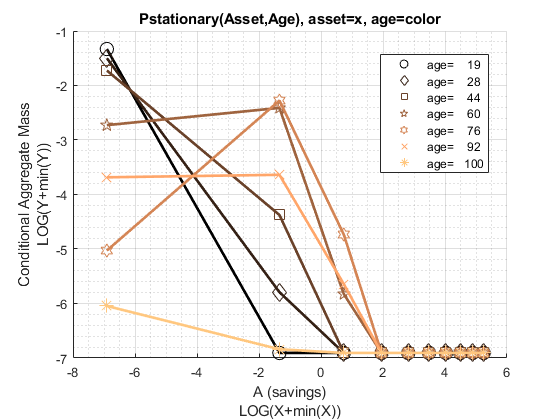

mp_support_graph('cl_st_graph_title') = {'Pstationary(Asset,Age), asset=x, age=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'age=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.0f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_aage{1:end, 3:end})', age_grid, agrid, mp_support_graph);% Consumption Choices

## Probability Statistics A, C and V Conditional on Ages

Where are the mass at?

Phi_true = mp_dsvfi_results('Phi_true');
ap_ss = mp_dsvfi_results('ap_ss');
c_ss = mp_dsvfi_results('c_ss');
v_ss = mp_dsvfi_results('v_ss');
n_ss = mp_dsvfi_results('n_ss');
for it_ctr=1:size(ap_ss, 1)
    display(['age =' num2str(age_grid(it_ctr))]);
    % construct input data
    Phi_true_age = Phi_true(it_ctr, :, :, : ,: ,:);
    ap_ss_age = ap_ss(it_ctr, :, :, : ,: ,:);
    c_ss_age = c_ss(it_ctr, :, :, : ,: ,:);
    v_ss_age = v_ss(it_ctr, :, :, : ,: ,:);
    n_ss_age = n_ss(it_ctr, :, :, : ,: ,:);
    
    mp_cl_ar_xyz_of_s = containers.Map('KeyType','char', 'ValueType','any');
    mp_cl_ar_xyz_of_s('ap_ss') = {ap_ss_age(:), zeros(1)};
    mp_cl_ar_xyz_of_s('c_ss') = {c_ss_age(:), zeros(1)};
    mp_cl_ar_xyz_of_s('v_ss') = {v_ss_age(:), zeros(1)};
    mp_cl_ar_xyz_of_s('n_ss') = {n_ss_age(:), zeros(1)};
    mp_cl_ar_xyz_of_s('ar_st_y_name') = ["ap_ss", "c_ss", "v_ss", "n_ss"];
    
    % controls
    mp_support = containers.Map('KeyType','char', 'ValueType','any');
    mp_support('ar_fl_percentiles') = [0.01 10 25 50 75 90 99.99];
    mp_support('bl_display_final') = true;
    mp_support('bl_display_detail') = false;    
    mp_support('bl_display_drvm2outcomes') = false;  
    mp_support('bl_display_drvstats') = false;
    mp_support('bl_display_drvm2covcor') = false;

    % Call Function     
    mp_cl_mt_xyz_of_s = ff_simu_stats(Phi_true_age(:)/sum(Phi_true_age,'all'), mp_cl_ar_xyz_of_s, mp_support);
end

age =19


xxx tb_outcomes: all stats xxx
    OriginalVariableNames       ap_ss         c_ss         v_ss          n_ss    
    _____________________    ___________    _________    _________    ___________

      {'mean'        }         0.0023837      0.63069      -2.6185         1.8895
      {'sd'          }          0.011937      0.20462       1.6033        0.93753
      {'coefofvar'   }            5.0079      0.32445     -0.61232        0.49618
      {'min'         }                 0      0.27581       -9.299              1
      {'max'         }               190       124.34       2.4353              4
      {'pYis0'       }           0.95644            0            0              0
      {'pYls0'       }                 0            0      0.99193              0
      {'pYgr0'       }          0.043563            1    0.0

age =28


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss         c_ss         v_ss          n_ss   
    _____________________    __________    _________    _________    __________

      {'mean'        }          0.01599      0.82374      -2.0592        2.0433
      {'sd'          }         0.053806      0.27535        1.482        1.0228
      {'coefofvar'   }           3.3649      0.33427      -0.7197       0.50056
      {'min'         }                0      0.34182      -7.6327             1
      {'max'         }              190       125.59       2.2758             4
      {'pYis0'       }          0.82062            0            0             0
      {'pYls0'       }                0            0      0.94137             0
      {'pYgr0'       }          0.17938            1     0.058628             

age =44


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss        v_ss        n_ss   
    _____________________    _________    ________    ________    _________

      {'mean'        }         0.17542     0.91179     -1.9125       2.0745
      {'sd'          }         0.16126     0.31229       1.385       1.0412
      {'coefofvar'   }         0.91925      0.3425    -0.72419      0.50189
      {'min'         }               0     0.42172     -6.9598            1
      {'max'         }          177.69      146.52      2.0495            4
      {'pYis0'       }        0.049221           0           0            0
      {'pYls0'       }               0           0     0.95035            0
      {'pYgr0'       }         0.95078           1    0.049649            1
      {'pYisMINY'    }        0.049221

age =60


xxx tb_outcomes: all stats xxx
    OriginalVariableNames       ap_ss         c_ss         v_ss          n_ss    
    _____________________    ___________    _________    _________    ___________

      {'mean'        }           0.37169      0.96085      -2.0154         2.0261
      {'sd'          }           0.29836      0.42294       1.4432         1.0203
      {'coefofvar'   }           0.80271      0.44017     -0.71606        0.50359
      {'min'         }          0.010464      0.37689      -7.7673              1
      {'max'         }             135.9       182.08       1.7303              4
      {'pYis0'       }                 0            0            0              0
      {'pYls0'       }                 0            0      0.98212              0
      {'pYgr0'       }                 1            1     0.

age =76


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss        v_ss         n_ss   
    _____________________    _________    ________    _________    _________

      {'mean'        }         0.22896     0.64184      -2.3069       1.9116
      {'sd'          }         0.36574     0.41779       1.3577      0.95668
      {'coefofvar'   }          1.5974     0.65091     -0.58854      0.50046
      {'min'         }               0     0.21429      -9.3041            1
      {'max'         }          96.845      224.04       1.3359            4
      {'pYis0'       }        0.048259           0            0            0
      {'pYls0'       }               0           0      0.93223            0
      {'pYgr0'       }         0.95174           1     0.067767            1
      {'pYisMINY'    }      

age =92


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss         c_ss         v_ss         n_ss   
    _____________________    __________    _________    ________    __________

      {'mean'        }         0.012754      0.61628     -2.5029        1.7645
      {'sd'          }         0.056227      0.68389      2.0369       0.85043
      {'coefofvar'   }           4.4085       1.1097    -0.81382       0.48197
      {'min'         }                0      0.21429     -7.2291             1
      {'max'         }           32.579       280.86      1.0167             4
      {'pYis0'       }          0.95106            0           0             0
      {'pYls0'       }                0            0     0.95106             0
      {'pYgr0'       }         0.048937            1    0.048937             1
      {'

age =100


xxx tb_outcomes: all stats xxx
    OriginalVariableNames    ap_ss      c_ss        v_ss        n_ss  
    _____________________    _____    ________    ________    ________

      {'mean'        }          0      0.26425     -3.9887      1.6334
      {'sd'          }          0      0.10266       1.148     0.72498
      {'coefofvar'   }        NaN      0.38849    -0.28781     0.44384
      {'min'         }          0      0.21429     -7.1327           1
      {'max'         }          0       313.44     0.99681           4
      {'pYis0'       }          1            0           0           0
      {'pYls0'       }          0            0           1           0
      {'pYgr0'       }          0            1           0           1
      {'pYisMINY'    }          1      0.38256     0.01599     0.49082
      {'pYisMAXY'